# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2023a on 21-Sep-2023 16:05:08

**Autor(es): Franck Michael Fierro Chicaiza**

**Fecha: 21/09/2023**

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("winvideo", 1, "YUY2_640x480");

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";

## Configure Device-Specific Properties

Configure properties that are specific to this device.

src = getselectedsource(v);
src.Brightness = 19;
src.Contrast = 15;
src.Exposure = -3;
src.Gain = 6;
src.Hue = -10;
src.Saturation = 39;

## Configure File Logging

Configure the device to log video to disk. Set the desired file location and name.

filelocation = "C:\Users\mfran\Desktop\Programas\Matlab";
filename = "recording1.avi";
fullFilename = fullfile(filelocation, filename);

% Create and configure the video writer
logfile = VideoWriter(fullFilename, "Motion JPEG AVI");

% Configure the device to log to disk using the video writer
v.LoggingMode = "disk";
v.DiskLogger = logfile;

## Record Continuous Video Data

Record video data continuously.

v.FramesPerTrigger = Inf;
start(v);

% Use INPUT to pause before ending acquisition.
input("Press ENTER to end acquisition.");
stop(v);

% Wait for all frames to be written to disk
while v.FramesAcquired ~= v.DiskLoggerFrameCount
    pause(.1);
end

## Show Recording

View the recorded video.

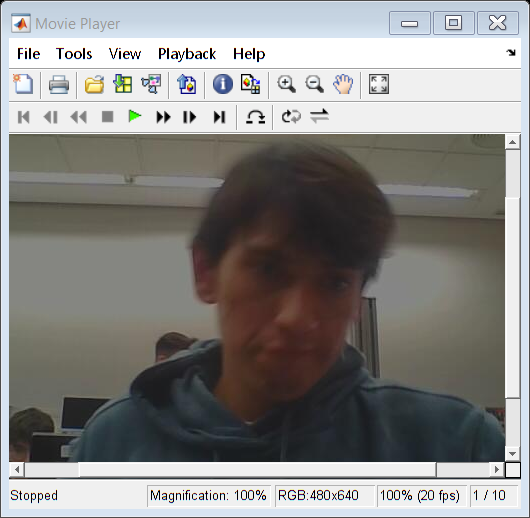

reader = VideoReader(fullFilename);
videoData = read(reader);
implay(videoData);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)
clear src v